# Assignment 1

### Given are two sets of measured lengths (in cm) of men (lengthmen)and women (lengthwomen) in the file lab1_1.mat.

load lab1_1.mat

#### 1.  Plot histograms of both sets in one figure.

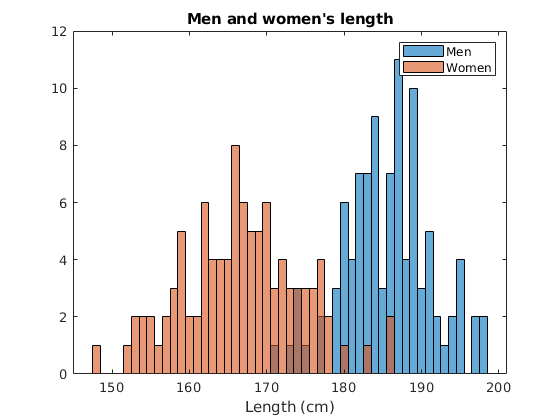

histogram(length_men)
hold on
histogram(length_women)
title("Men and women's length")
xlabel('Length (cm)')
legend('Men', 'Women')
hold off

#### 2.  Now choose the decision criterion at 170 cm. How many men are classified incorrect? And how many women?

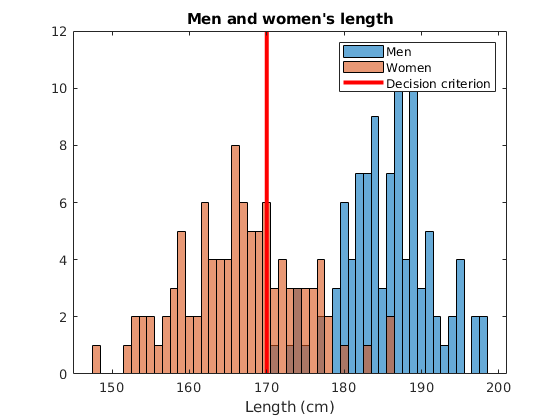

hold on
% Draw a vertical line at 170 cm
line([170, 170], ylim, 'LineWidth', 3, 'Color', 'r')
legend('Men', 'Women', 'Decision criterion')
hold off


% Misclassified men are shorter or equal than 170 cm
nIncMen = length(length_men(length_men <= 170));
fprintf('Men classified incorrect: %i', nIncMen)

Men classified incorrect: 0


% Misclassified women are taller than 170 cm
nIncWomen = length(length_women(length_women > 170));
fprintf('Women classified incorrect: %i', nIncWomen)

Women classified incorrect: 29

#### 3.  What decision criterion should be used to minimize total number of mis-classifications (sum over men and women)?

min = nIncMen + nIncWomen;
d_criterion = 170;

% The optimal decision criterion is between 150 cm and 200 cm
for i = 150:200
    
    % Firstly, calculate misclassifications
    nIncMenAux = length(length_men(length_men <= i));
    nIncWomenAux = length(length_women(length_women > i));
    
    % If it's lower than the minimum, then it becomes the new minimum
    if min > nIncMenAux + nIncWomenAux
        min = nIncMenAux + nIncWomenAux;
        d_criterion = i;
        nIncMen = nIncMenAux;
        nIncWomen = nIncWomenAux;
    end
end

fprintf('Best decision criterion: %i', d_criterion)

Best decision criterion: 178

fprintf('Men classified incorrect: %i', nIncMen)

Men classified incorrect: 8

fprintf('Women classified incorrect: %i', nIncWomen)

Women classified incorrect: 4